Homework 5

Shaobo Wang

Question 1.

clear;clc

(a) 

Assume $a=100$, the system plant model is:


$$G(s)=\frac{1}{s^2+2s+10000}
\left[\matrix{s-10000&100(s+1)\cr -100(s+1)&s-10000}\right]$$


s = tf('s');
a = 100;
G = (1/(s^2+a/50*s+a^2))*[s-a^2,a*(s+1);-a*(s+1),s-a^2];

Find the poles of the system:

p = roots([1,a/50,a^2])

p =   -1.0000 +99.9950i
  -1.0000 -99.9950i


Find the directions with SVD by choosing the vector corresponding to $\bar\sigma$:

Gp1 = evalfr(G,p(1));
[Up1,Sp1,Vp1] = svd(Gp1);

Output direction of the first pole:

outdirp1 = Up1(:,1)

outdir1 =   -0.7071 + 0.0035i
  -0.0035 - 0.7071i


Input direction of the first pole:

indirp1 = Vp1(:,1)

indir1 =    0.7071 + 0.0000i
   0.0000 + 0.7071i


Gp2 = evalfr(G,p(2));
[Up2,Sp2,Vp2] = svd(Gp2);

Output direction of the second pole:

outdirp2 = Up2(:,1)

outdir2 =   -0.7071 - 0.0035i
  -0.0035 + 0.7071i


Input direction of the second pole:

indirp2 = Vp2(:,1)

indir2 =    0.7071 + 0.0000i
   0.0000 - 0.7071i


Find the zeros of the system:

z = tzero(minreal(G))

z =    0.0000 +100.0000i
   0.0000 -100.0000i


Find the directions with SVD by choosing the vector corresponding to $\underline\sigma$:

Gz1 = evalfr(G,z(1));
[Uz1,Sz1,Vz1] = svd(Gz1);

Uz1 =   -0.0071 - 0.7071i  -0.2315 - 0.6682i
   0.7071 - 0.0071i  -0.6682 + 0.2315i


Sz1 =   100.0050         0
         0    0.0000


Vz1 =   -0.7071 + 0.0000i  -0.7071 + 0.0000i
   0.0000 - 0.7071i   0.0000 + 0.7071i


Output direction of the first zero:

outdirz1 = Uz1(:,1)

Input direction of the first zero:

indirz1 = Vz1(:,1)

Uz2 =   -0.0071 + 0.7071i  -0.2315 + 0.6682i
   0.7071 + 0.0071i  -0.6682 - 0.2315i


Sz2 =   100.0050         0
         0    0.0000


Vz2 =   -0.7071 + 0.0000i  -0.7071 + 0.0000i
   0.0000 + 0.7071i   0.0000 - 0.7071i


Gz2 = evalfr(G,z(2));
[Uz2,Sz2,Vz2] = svd(Gz2)

Output direction of the second zero:

outdirz2 = Uz2(:,1)

Input direction of the second zero:

indirz2 = Vz2(:,1)

(b) The rank of a matrix will not change if a full rank matrix is multiplied to original matrix:


$$\left[\matrix{A-sI+BK&B\cr C+DK&D}\right]
=\left[\matrix{A-sI&B\cr C&D}\right]\left[\matrix{I&O\cr K&I}\right]$$


The matrix $\left[\matrix{I&O\cr K&I}\right]$is always full rank because of its diagonal entries are all ones. 

Therefore, the rank of system matrix will not be affected by the state feedback:


$$rank(\left[\matrix{A-sI+BK&B\cr C+DK&D}\right])
=rank(\left[\matrix{A-sI&B\cr C&D}\right])$$


Problem 2

(a) Define signal $e = r-y$, the equivalent system block diagram is:

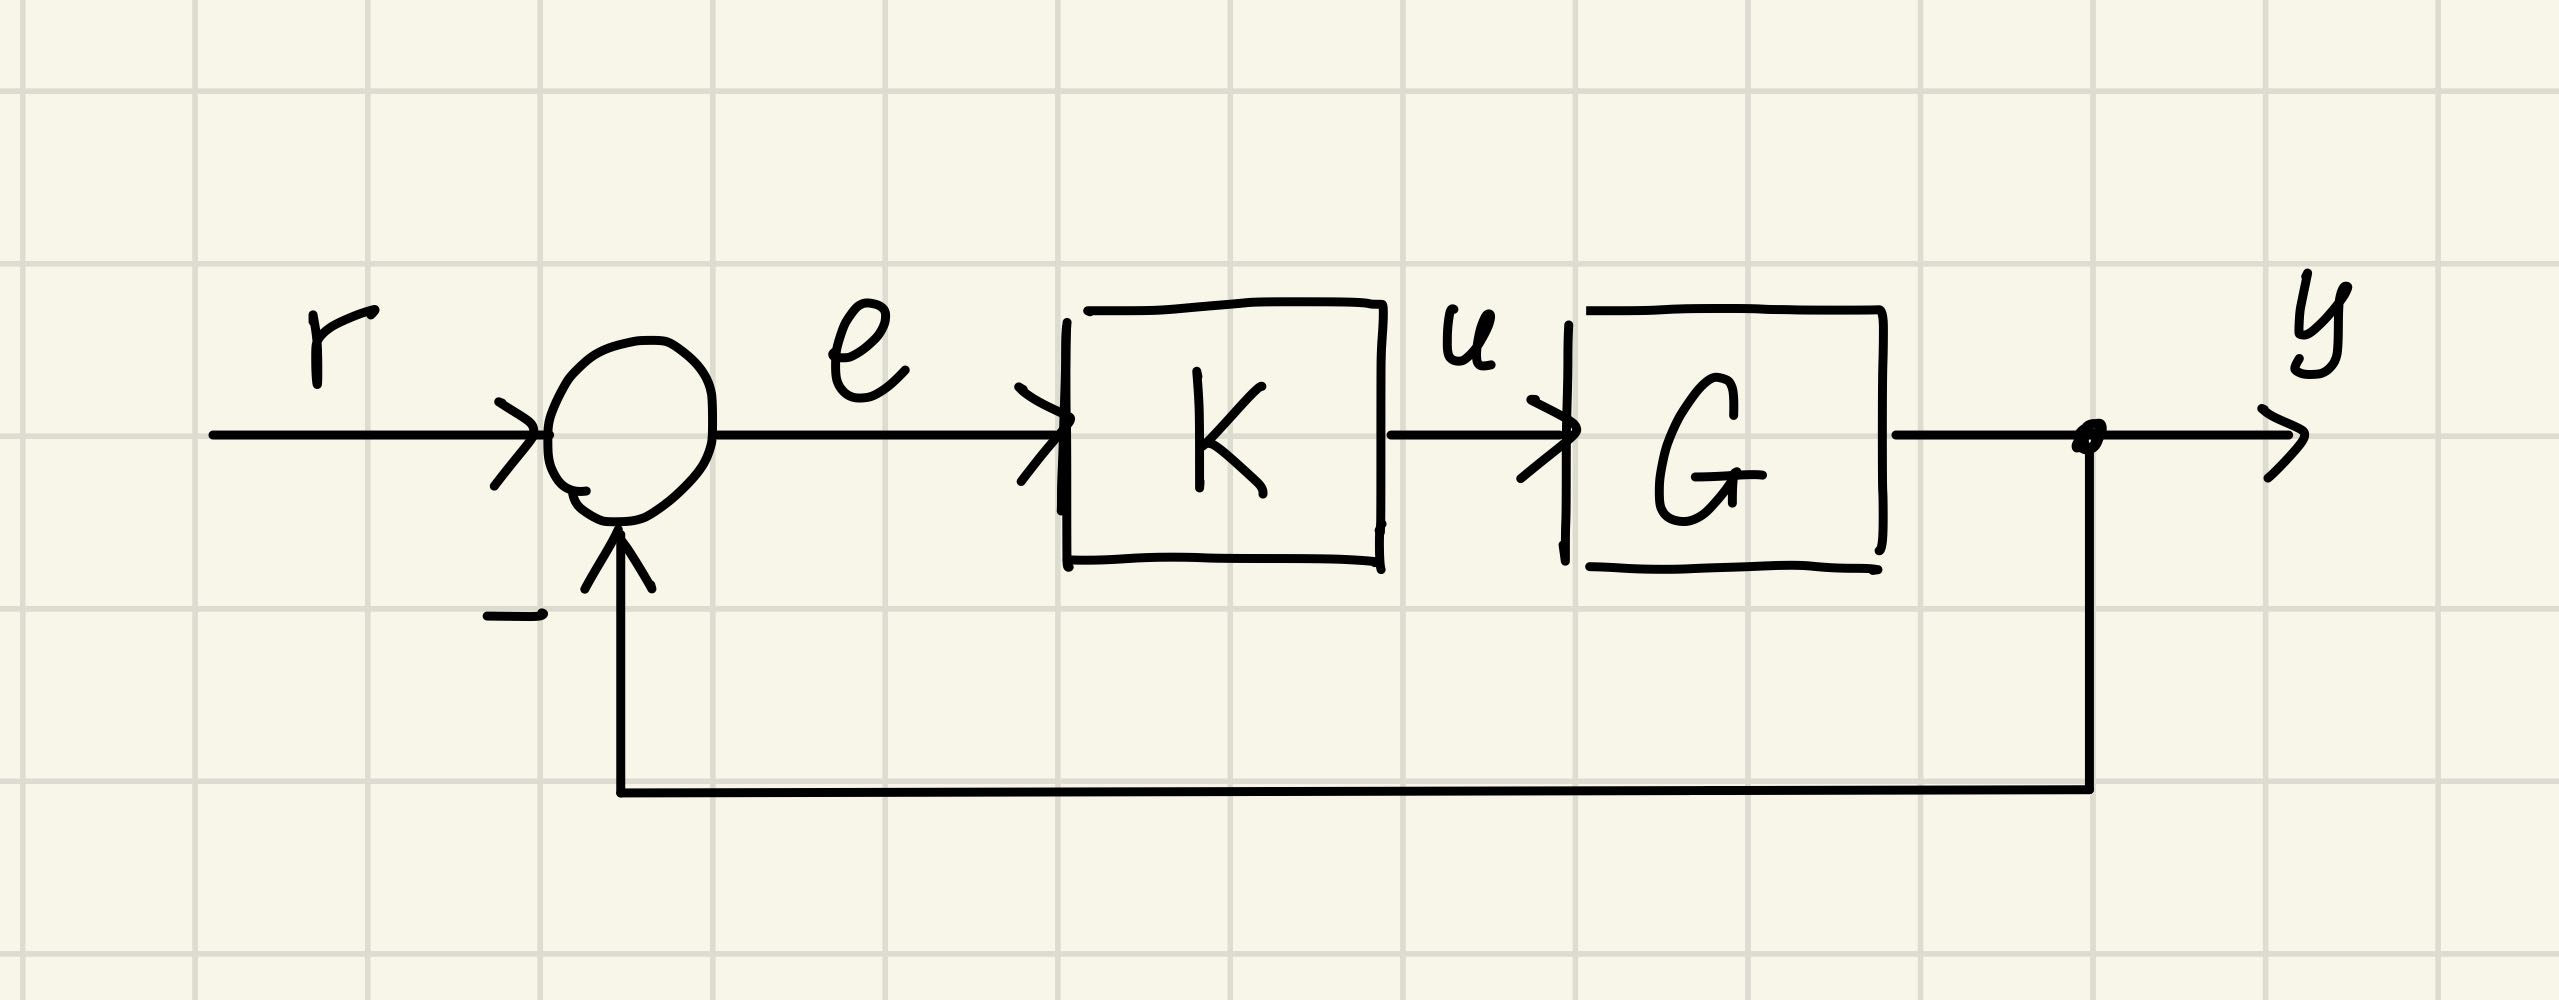

Assume $d_y=0$, derive the TF of $K$


$$\begin{cases}
e = r-y = r - GQr \\
u = Qr
\end{cases}
\Rightarrow
u = Q(I-GQ)^{-1}e
\Rightarrow K = Q(I-GQ)^{-1}$$


Solve for $Q$ in terms of $K$:


$$Q = (I+KG)^{-1}K=K(I+GK)^{-1}$$


A system is internally stable if and only if $K(I+GK)^{-1}$is stable.

Therefore, if $Q$ is unstable, the IMC structure is internally unstable.

(b)  Write out all the output signal in terms of input signal of the following system:

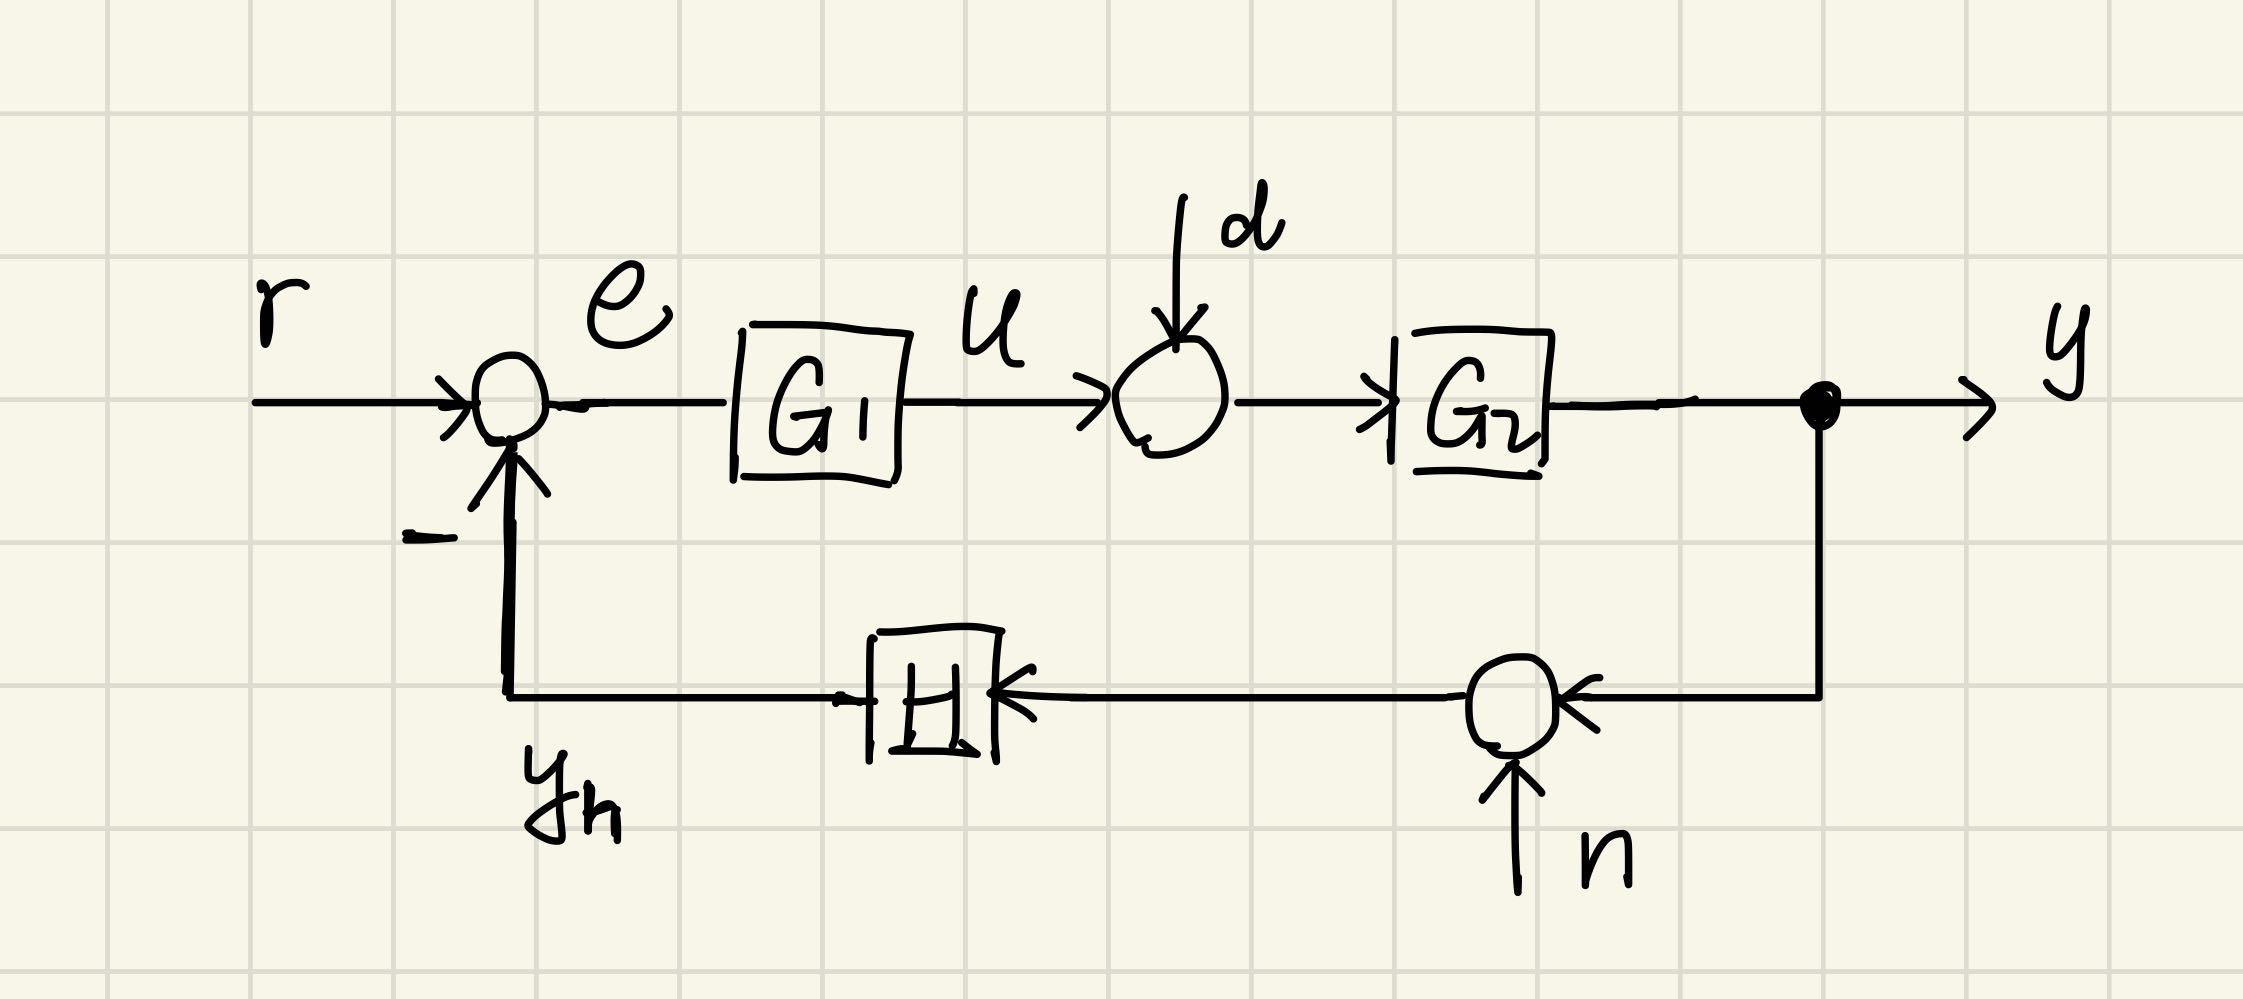


$$y=(I+G_2G_1H)^{-1}G_2d+(I+G_2G_1H)^{-1}G_2G_1r-(I+G_2G_1H)^{-1}G_2G_1Hn\\

u = (I+G_1HG_2)^{-1}G_1r-(I+G_1HG_2)^{-1}G_1Hn-(I+G_1HG_2)^{-1}G_1HG_2d\\

y_h = (I+HG_2G_1)^{-1}Hn+(I+HG_2G_1)^{-1}HG_2d+(I+HG_2G_1)^{-1}HG_2G_1r$$


Therefore, there are nine conditions in total to meet in order for the system to be internally stable:


$$\begin{cases}
(I+G_2G_1H)^{-1}G_2=G_2(I+G_1HG_2)^{-1}\\
(I+G_2G_1H)^{-1}G_2G_1=G_2(I+G_1HG_2)^{-1}G_1\\
(I+G_2G_1H)^{-1}G_2G_1H=G_2(I+G_1HG_2)^{-1}G_1H\\
(I+G_1HG_2)^{-1}G_1\\
(I+G_1HG_2)^{-1}G_1H\\
(I+G_1HG_2)^{-1}G_1HG_2\\
(I+HG_2G_1)^{-1}H = H(I+G_1HG_2)^{-1}\\
(I+HG_2G_1)^{-1}HG_2=H(I+G_1HG_2)^{-1}G_2\\
(I+HG_2G_1)^{-1}HG_2G_1=H(I+G_1HG_2)^{-1}G_2G_1\\
\end{cases}$$


Define $Q = G_2(I+G_1HG_2)^{-1}$, we can proof: $\begin{cases}
(I+G_1HG_2)^{-1}=I-G_1HQ\\
(I+G_2G_1H)^{-1} = I-QG_1H
\end{cases}$ 


$$\begin{cases}
(I+G_2G_1H)^{-1}G_2=G_2(I+G_1HG_2)^{-1} = Q\\
(I+G_2G_1H)^{-1}G_2G_1=G_2(I+G_1HG_2)^{-1}G_1 = QG_1\\
(I+G_2G_1H)^{-1}G_2G_1H=G_2(I+G_1HG_2)^{-1}G_1H = QG_1H\\
(I+G_1HG_2)^{-1}G_1 = (I-G_1HQ)G_1\\
(I+G_1HG_2)^{-1}G_1H = (I-G_1HQ)G_1H\\
(I+G_1HG_2)^{-1}G_1HG_2 = I-(I+G_1HG_2)^{-1}=G_1HQ\\
(I+HG_2G_1)^{-1}H = H(I+G_2G_1H)^{-1} = H(I-QG_1H)\\
(I+HG_2G_1)^{-1}HG_2=HG_2(I+G_1HG_2)^{-1} = HQ\\
(I+HG_2G_1)^{-1}HG_2G_1=I-(I+HG_2G_1)^{-1} = QG_1H\\
\end{cases}$$


All nine conditions can be written in terms of $Q,G_1,H$. 

Therefore, if $H(s),G_1(s)$ are both stable, the condition for internal stability of  the feedback system is $Q(s)$ stable.

Problem 3

The RHP zero and pole of the plant model are:


$$\begin{cases}
z = 1\\
p=2
\end{cases}$$


Design the weight shape for a conventional loop shape.

Since we already know it's impossible to maintain conventions with those RHP zeros and poles, just boldly assume $M = 3,A = 0,M_T = 3$.

(1) bandwidth limitations

For sensitivity bandwidth, since $|S|=1$at the RHP zero, 


$$1>\|W_pS\|_{\infty}\geq \frac{|1+2|}{|1-2|}|W_p(1)|=3|W_p(1)|
\Rightarrow
|W_p(1)|<\frac{1}{3}$$


The sensitivity weight is:


$$W_p(s) = \frac{s/M+\omega_{BW}}{s+\omega_{BW}A}=1/3+\omega_{BW}/s$$


Therefore, the $S$ bandwidth limit is:


$$|1/3+\omega_{BW}|<1/3 \Rightarrow \omega_{BW}<0$$


For complementary sensitivity bandwidth, since $|T|=1$at the RHP pole,


$$1>\|W_TT\|_{\infty}\geq \frac{|1+2|}{|1-2|}|W_T(2)|=3|W_T(2)|
\Rightarrow
|W_T(2)|<\frac{1}{3}$$


The complementary sensity weight is:


$$W_T(s) = s/{\omega_{BT}}+1/M_T=s/{\omega_{BT}}+1/3$$


Therefore, the $T$ bandwidth limit is:


$$|2/\omega_{BW}+1/3|<1/3 \Rightarrow \omega_{BW}>\infty$$


This contradictory result basically means the desired loopshape cannot be met with RHP poles and zeros.

(2) minimum peak

Since we only have one RHP zero and one RHP pole, the sensitivity peak is:


$$\min_K\|S\|_{\infty} = \sqrt{\frac{|z+p|^2}{|z-p|^2}} = \sqrt{\frac{|1+2|^2}{|1-2|^2}}=3$$
